%https://www.mathworks.com/content/dam/mathworks/tag-team/Objects/c/88360_93001v00_Color-Based_Seg_K-Means_Clustering_2016.pdf

addpath('databas2')
allSize = 7128;
database = cell(1,allSize);

for i = 1:size(database,2)
    fileName = strcat(int2str(i),'.jpg');
    img = im2double(imread(fileName));
    database{i} = img;
end

allChannels = zeros(3,allSize)

allChannels =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


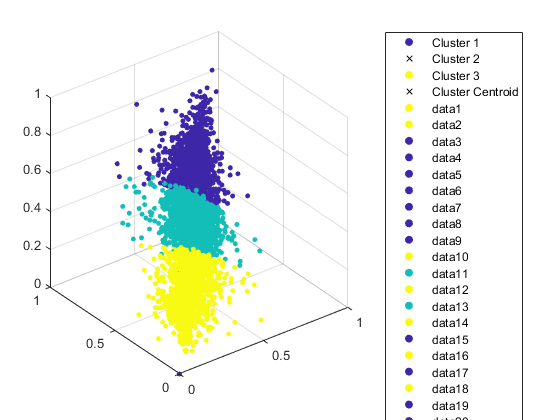


for i = 1:allSize
    
    fileName = strcat(int2str(i),'.jpg');
    img = im2double(imread(fileName));
    allChannels(1,i) = mean(mean(img(:, :, 1)));
    allChannels(2,i) = mean(mean(img(:, :, 2)));
    allChannels(3,i) = mean(mean(img(:, :, 3)));
end
X = allChannels';
[idx,C] = kmeans(X,3);

scatter3(X(:,1),X(:,2),X(:,3),15,idx,'filled')

cluster1 = cell(1,allSize);
cluster2 = cell(1,allSize);
cluster3 = cell(1,allSize);

for i = 1:allSize
    if idx(i,1) == 1
        cluster1(i) = database(1,i);
    end
    if idx(i,1) == 2
        cluster2(i) = database(1,i);
    end
    if idx(i,1) == 3
        cluster3(i) = database(1,i);
    end
end

cluster1(:, any(cellfun(@isempty, cluster1), 1)) = [];
cluster2(:, any(cellfun(@isempty, cluster2), 1)) = [];
cluster3(:, any(cellfun(@isempty, cluster3), 1)) = [];

meanClus1 = 0;
meanClus2 = 0;
meanClus3 = 0;



for i = 1:size(cluster1(2))
    lab1 = rgb2lab(cell2mat(cluster1(i)));
    meanClus1 = meanClus1 + mean(mean(lab1));
end
for i = 1:size(cluster2(2))
    lab2 = rgb2lab(cell2mat(cluster2(i)));
    meanClus2 = meanClus2 + mean(mean(lab2));
end
for i = 1:size(cluster3(2))
    lab3 = rgb2lab(cell2mat(cluster3(i)));
    meanClus3 = meanClus3 + mean(mean(lab3));
end

meanClus1 = meanClus1/size(cluster1(1,2),2)

meanClus1 = meanClus1(:,:,1) =

   54.9866


meanClus1(:,:,2) =

   -0.3026


meanClus1(:,:,3) =

  -14.4064


meanClus2 = meanClus2/size(cluster2(1,2),2)

meanClus2 = meanClus2(:,:,1) =

   51.5204


meanClus2(:,:,2) =

   -1.1577


meanClus2(:,:,3) =

   23.4267


meanClus3 = meanClus3/size(cluster3(1,2),2)

meanClus3 = meanClus3(:,:,1) =

   40.6476


meanClus3(:,:,2) =

  -24.1116


meanClus3(:,:,3) =

   32.3305
